# Recursive Least Square

## Practice 1: Estimate mass of vehicle

### Problem

There is an accelerating vehicle. This vehicle is a **two-wheel drive**, and the **diameter** of each wheel is **600 mm**.

If we can control the torque of the wheel, use the **input torque** and **measured acceleration** to determine the **mass of the vehicle**.

The torque is the value for one wheel.

(Assume that the torque is transferred to the ground without any errors or losses.)

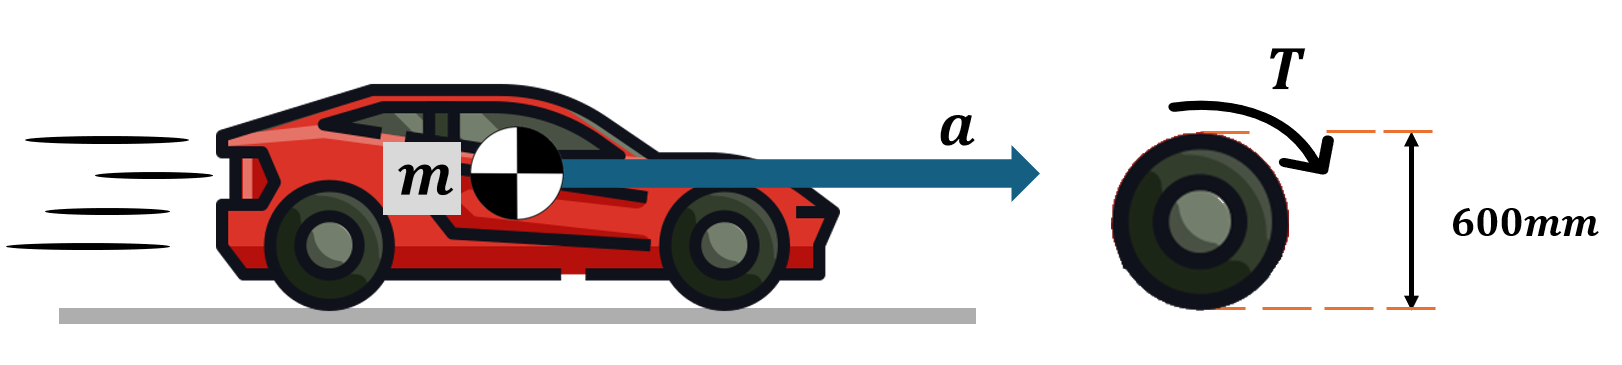

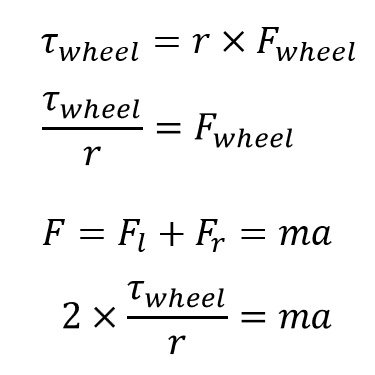

- τ_wheel : Wheel **torque**

- r : **Radius** of the wheel

- F_wheel : Wheel **force**

- F : **Total force** applied to the vehicle

- F_l : **Force** due to the **left wheel**

- F_r : **Force** due to the **right wheel**

- m : **Mass** of the vehicle

- a : **Acceleration** of the vehicle

### Measurement data

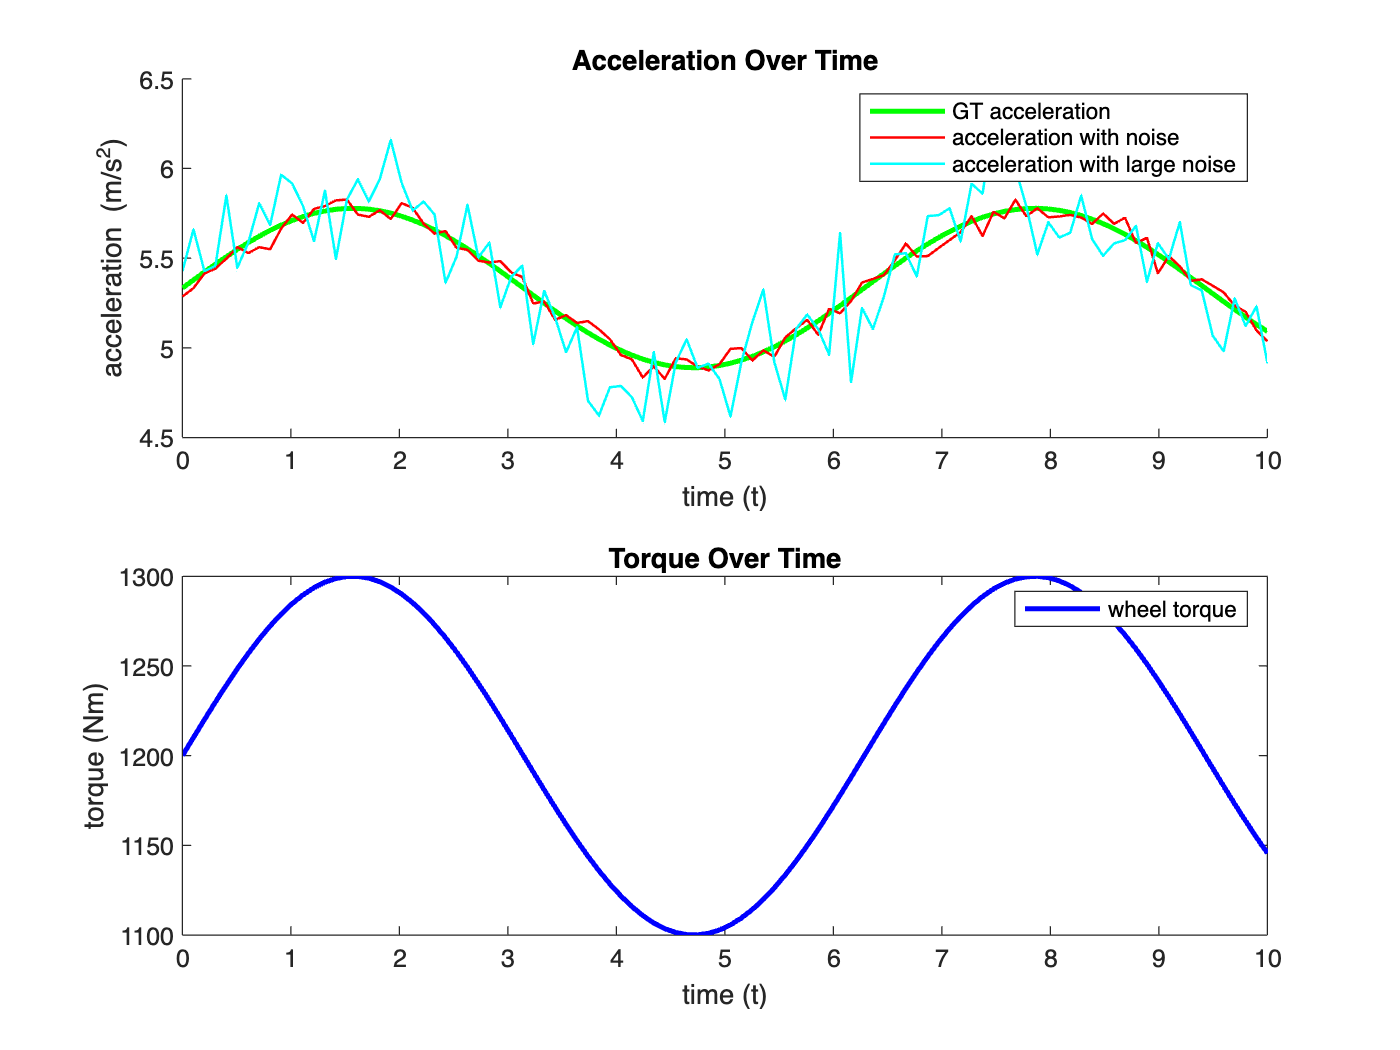

clear; close all;
load('least_square_mat_file_practice1.mat');
sim_total_steps = length(time);

figure;
subplot(2,1,1);
hold on;
plot(time, gt_accelerations_mps2, 'g-', 'LineWidth', 2);
plot(time, accelerations_with_noise_mps2, 'r-', 'LineWidth', 1);
plot(time, accelerations_with_large_noise_mps2, 'c-', 'LineWidth', 1);
xlabel('time (t)');
ylabel('acceleration (m/s^2)');
legend('GT acceleration', 'acceleration with noise','acceleration with large noise');
title('Acceleration Over Time');

subplot(2,1,2);
plot(time, torques_Nm, 'b-', 'LineWidth', 2);
xlabel('time (t)');
ylabel('torque (Nm)');
legend('wheel torque');
title('Torque Over Time');
hold off;

### Recursive least square modeling

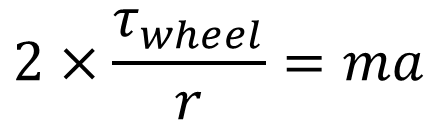

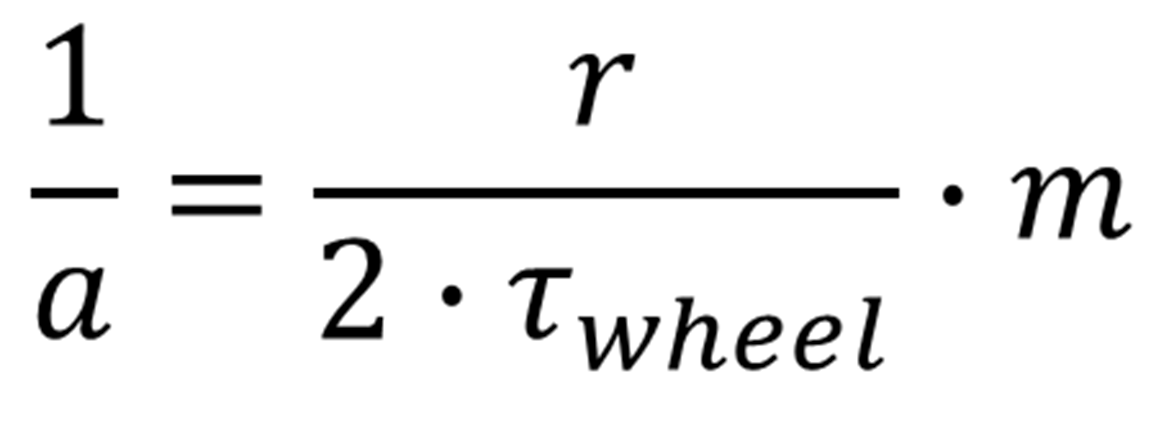

#### Least square modeling

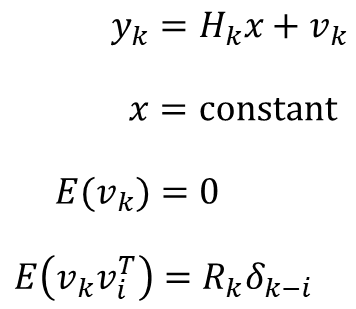

- 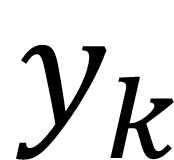: measurement vector

- 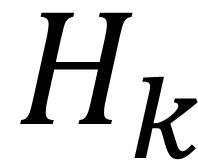: measurement matrix

- 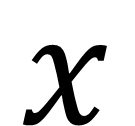: state vector

#### Initialization

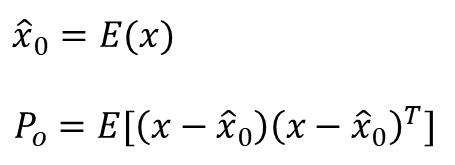

- 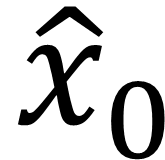: Initial estimated state vector

- 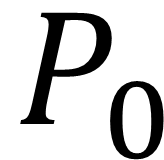: Initial estimation-error covariance

#### Recursive estimation

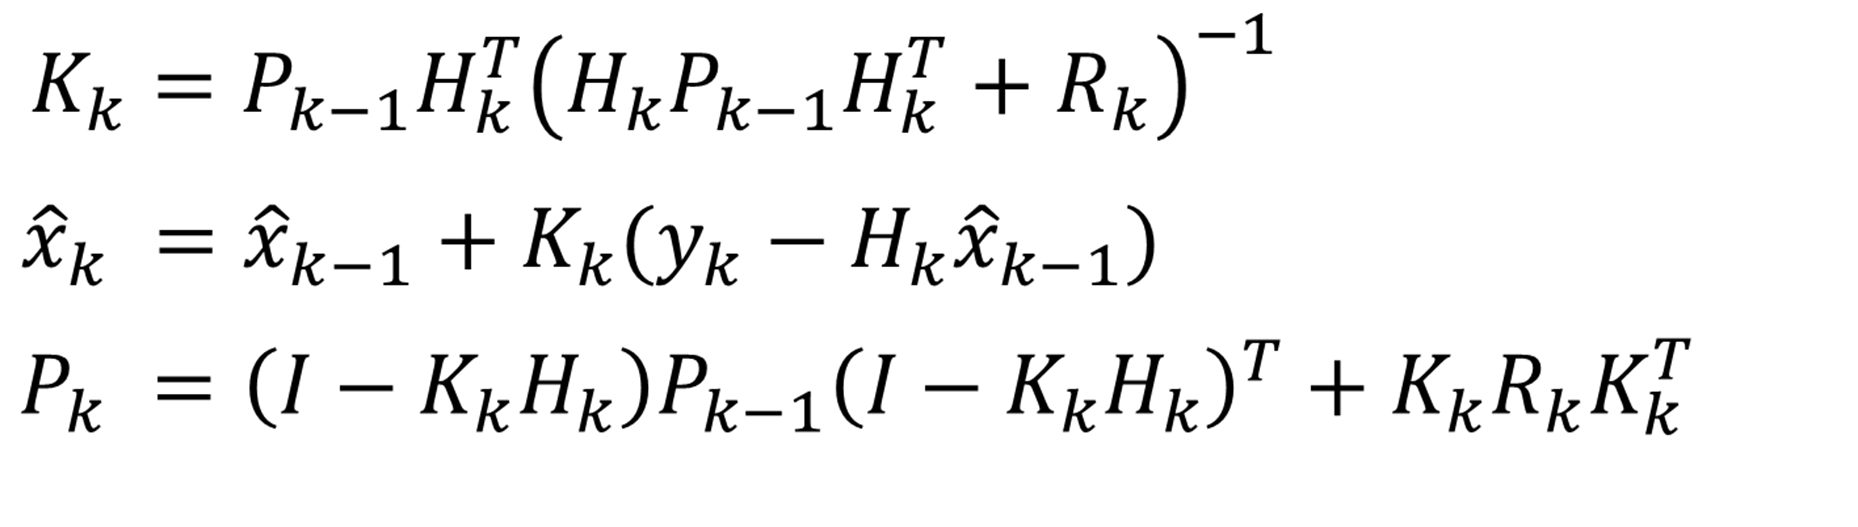

- 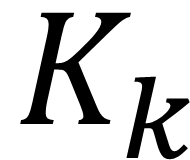: estimator gain matrix

- 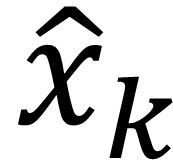: estimated state vector

- 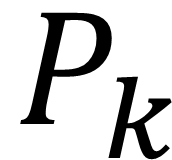: estimation-error covariance

Num_of_state = 1; % mass_kg
Num_of_measurement_order = 1; % acceleration
H = zeros(sim_total_steps, Num_of_state);
Y = zeros(sim_total_steps, Num_of_measurement_order);

x_rls = zeros(Num_of_state, sim_total_steps);
P_rls = cell(sim_total_steps,1);

% Initialize
x0 = 1000;
P0 = 1e+10;

% ToDo: Determine measurement covariance matrix R
R = 0.05^2;    % example

isFirstStep = true;
for idxSim = 1: sim_total_steps
    if isFirstStep == true
        x_rls(:,idxSim) = x0;
        P_rls{idxSim} = P0;
        isFirstStep = false;
    else
        prev_x = x_rls(:, idxSim-1);
        prev_p = P_rls{idxSim-1};
    
        %%%% TODO %%%%
        % Modeling H_k matrix
        H(idxSim,:) = wheel_radius_m / (2 * torques_Nm(idxSim));
     
    
        % Determine gain K_k
        K = P_rls{idxSim-1}*H(idxSim,:)'*(H(idxSim,:)*P_rls{idxSim-1}*H(idxSim,:)' + R)^(-1);

    
        % Define the measurement Y_k
        % Y(idxSim,:) = 1/accelerations_with_noise_mps2(idxSim);
        Y(idxSim,:) = 1/accelerations_with_large_noise_mps2(idxSim);

    
        % Update estimating state \hat(x)_k
        x_rls(:,idxSim) = x_rls(:,idxSim-1) + K*(Y(idxSim,:) - H(idxSim,:)*x_rls(:,idxSim-1));
    

        % Update uncertainty P_k
        P_rls{idxSim} = (eye(Num_of_state) - K*H(idxSim, :)) * P_rls{idxSim-1} * (eye(Num_of_state) - K*H(idxSim))' + K*R*K';
    end
end


Estimated mass: 1507.24 kg


estimated_mass = x_rls(:, sim_total_steps);

GT mass: 1500.00 kg



% Estimated result
fprintf('Estimated mass: %.2f kg\n', estimated_mass);
fprintf('GT mass: %.2f kg\n', gt_mass_kg);

### Visualize Result

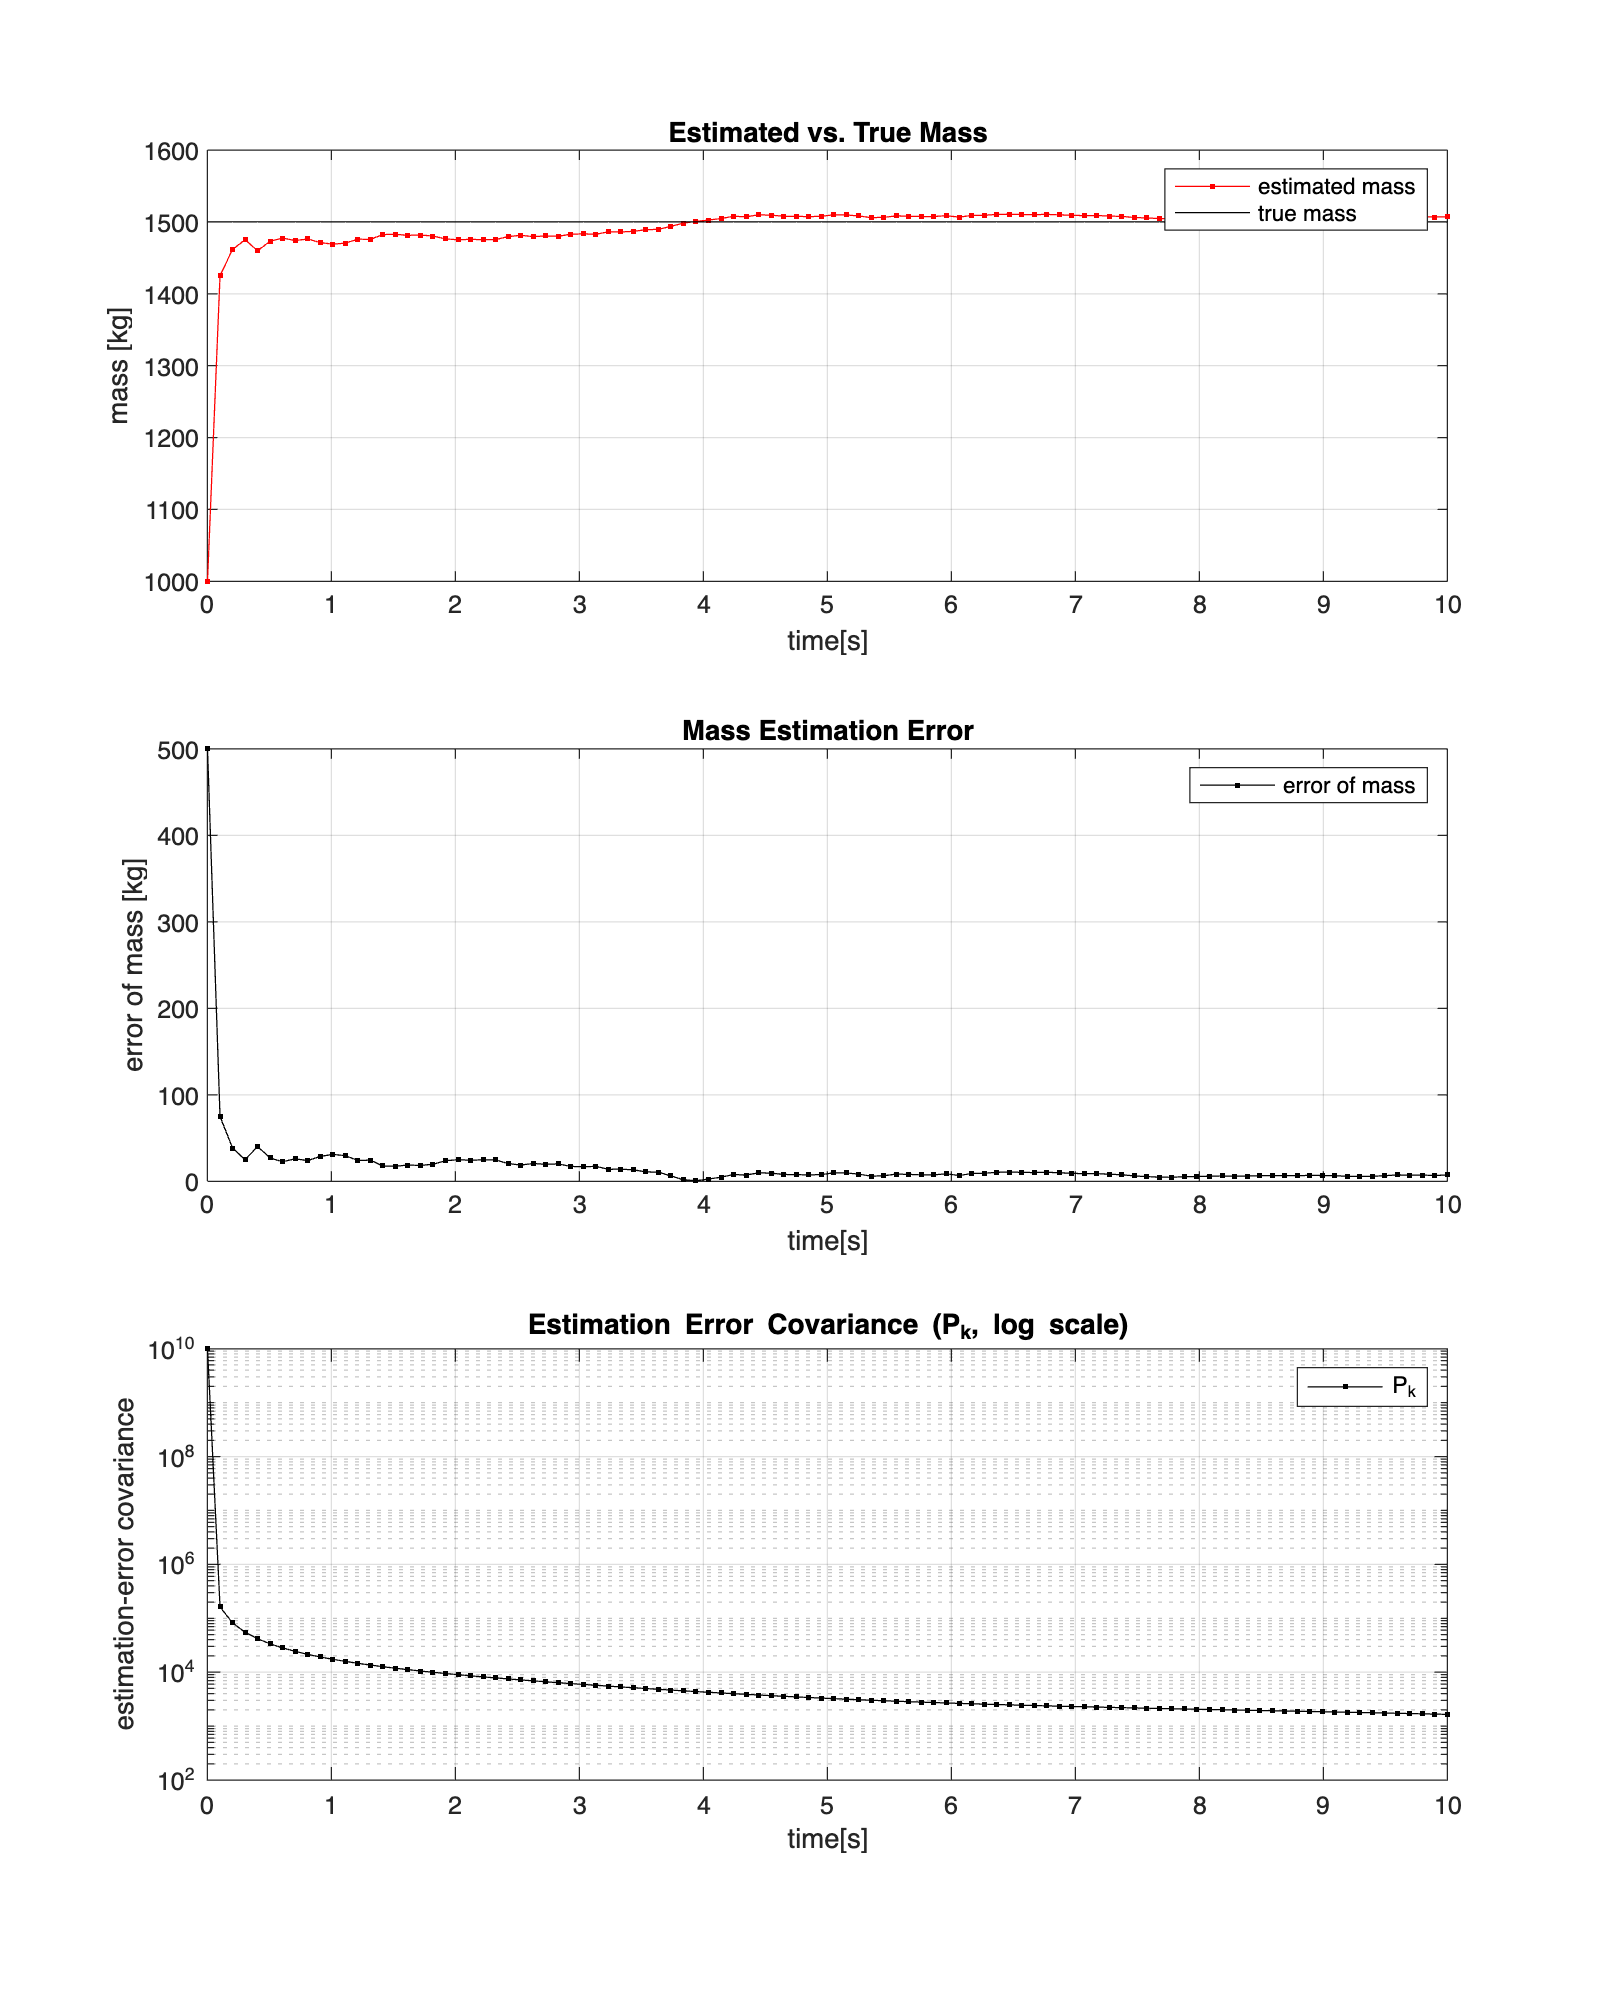

error_rls = abs(x_rls - gt_mass_kg);

figure('Name','[Practice 1: State and Covariance]','Position',[100,100,800,1000]);
subplot(3,1,1)
plot(time, x_rls(1,:), 'r.-');
hold on;
plot(time, gt_mass_kg * ones(sim_total_steps,1),'k');
legend('estimated mass','true mass'); 
title('Estimated vs. True Mass');
xlabel('time[s]');
ylabel('mass [kg]');
grid on; hold off;

subplot(3,1,2)
plot(time, error_rls(1,:), 'k.-');
legend('error of mass'); 
title('Mass Estimation Error');
xlabel('time[s]');
ylabel('error of mass [kg]');
grid on;

subplot(3,1,3)
P_rls_mat = cell2mat(P_rls)';
semilogy(time, P_rls_mat(1,:), 'k.-');
legend('P_k'); 
title('Estimation Error Covariance (P_k, log scale)');
xlabel('time[s]');

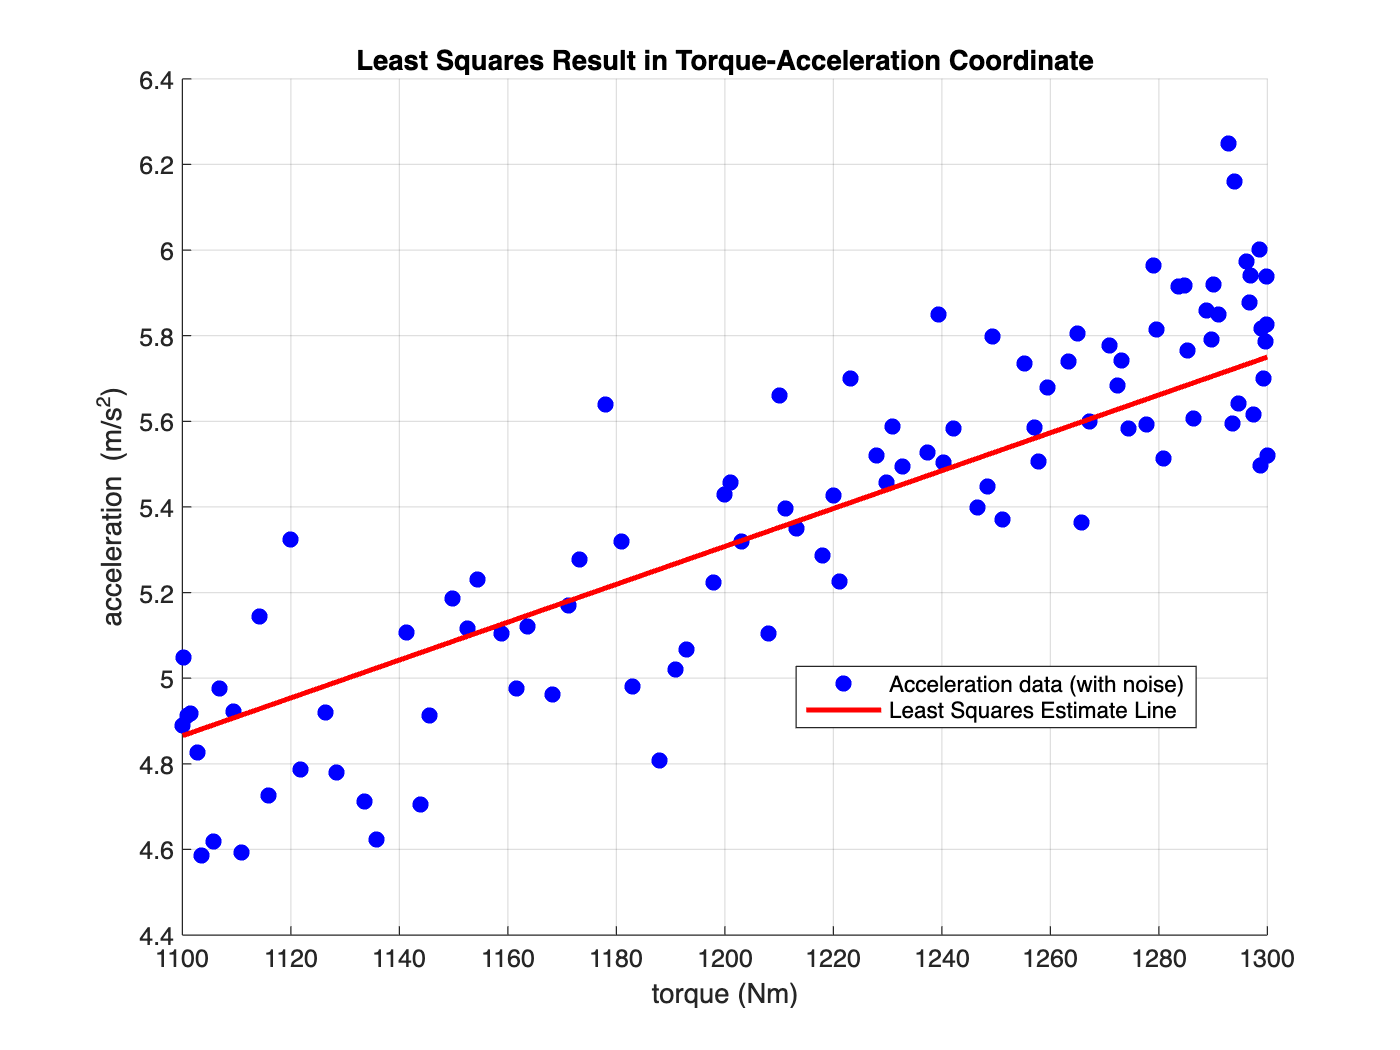

ylabel('estimation-error covariance');
grid on;
figure;
hold on;
plot(torques_Nm, accelerations_with_large_noise_mps2, 'bo', 'MarkerFaceColor', 'b');
torques_line = linspace(min(torques_Nm), max(torques_Nm), 100);
accelerations_line = (2 * torques_line / wheel_radius_m) / estimated_mass;
plot(torques_line, accelerations_line, 'r-', 'LineWidth', 2);
xlabel('torque (Nm)');
ylabel('acceleration (m/s^2)');
title('Least Squares Result in Torque-Acceleration Coordinate');
legend('Acceleration data (with noise)', 'Least Squares Estimate Line', 'Location', 'best');

grid on;
hold off;